# The goal for this version is to introduce Phase variant LGN input

LGN is still fake, but will add more realistic factors...

CurrentFolder = pwd
FigurePath = [CurrentFolder '/Figures'];
addpath(CurrentFolder)
addpath([CurrentFolder '/Utils'])
addpath([CurrentFolder '/Data'])
SaveFolder = [CurrentFolder '/Figures/Demo060521/'];
addpath(SaveFolder)
DataFolder = [CurrentFolder '/Figures/Demo042221/'];
addpath(DataFolder)

First read old network structure, get our desired Numbers of presyn neurons

load('NtWk_Archit.mat')
E_sideInd = floor(1*n_E_HC+1):2*n_E_HC;
[E_Ind_X,E_Ind_Y] = meshgrid(E_sideInd,E_sideInd);
E_Ind = (reshape(E_Ind_X,size(E_Ind_X,1)*size(E_Ind_X,2),1)-1)*n_E_HC*N_HC + reshape(E_Ind_Y,size(E_Ind_X,1)*size(E_Ind_X,2),1);
I_sideInd = floor(1*n_I_HC+1):2*n_I_HC;
[I_Ind_X,I_Ind_Y] = meshgrid(I_sideInd,I_sideInd);
I_Ind = (reshape(I_Ind_X,size(I_Ind_X,1)*size(I_Ind_X,2),1)-1)*n_I_HC*N_HC + reshape(I_Ind_Y,size(I_Ind_X,1)*size(I_Ind_X,2),1);

N_EE = full(mean(sum(C_EE(E_Ind,:),2))); N_EI = full(mean(sum(C_EI(E_Ind,:),2))*0.75); %*0.75
N_IE = full(mean(sum(C_IE(I_Ind,:),2))); N_II = full(mean(sum(C_II(I_Ind,:),2))*0.75); %*0.75 Plan A:Original

Then use the new function to generate new network stucture


%% If now, we start computation below...
% Frst setup network
N_HC = 3;
% Number of E and I neurons
n_E_HC = 54; n_I_HC = 31; % per side of HC
N_E = n_E_HC^2 * N_HC^2; % neuron numbers In all
N_I = n_I_HC^2 * N_HC^2;
% Grid sizes of E and I neurons;
Size_HC = 0.500; % in mm;
Size_E = Size_HC/n_E_HC; Size_I = Size_HC/n_I_HC;
% Projection: SD of distances
SD_E = 0.2/sqrt(2); SD_I = 0.125/sqrt(2);
Dist_LB = 0.36; % ignore the connection probability of dist>0.3mm
% Peak probability of projection
Peak_EE = 0.15; Peak_I = 0.6;

% spatial indexes of E and I neurons
[NnE.X,NnE.Y] = V1Field_Generation(N_HC,1:N_E,'e');
[NnI.X,NnI.Y] = V1Field_Generation(N_HC,1:N_I,'i');

% determine connections between E, I sparse metrices containing 0 or 1.
% Row_i Column_j means neuron j projects to neuron i add periodic boundary

C_EE_Fix = ConnectionMat_Fix(N_E,NnE,Size_E,...currentVec(2)^2
    N_E,NnE,Size_E,...
    Peak_EE,SD_E,Dist_LB,1, round(N_EE));

C_EI_Fix = ConnectionMat_Fix(N_E,NnE,Size_E,...
    N_I,NnI,Size_I,...
    Peak_I,SD_I,Dist_LB,0, round(N_EI));

C_IE_Fix = ConnectionMat_Fix(N_I,NnI,Size_I,...
    N_E,NnE,Size_E,...
    Peak_I,SD_E,Dist_LB,0, round(N_IE));

C_II_Fix = ConnectionMat_Fix(N_I,NnI,Size_I,...
    N_I,NnI,Size_I,...
    Peak_I,SD_I,Dist_LB,1, round(N_II));

## Variables and Parameters

fixed parameters

p_EEFail = 0.2; S_amb = 0.01;
rE_amb = 0.500; rI_amb = 0.500;

tau_ampa_R = 0.5; tau_ampa_D = 3;
tau_nmda_R = 2; tau_nmda_D = 80;
tau_gaba_R = 0.5; tau_gaba_D = 5;
tau_ref = 2; % time unit is ms

gL_E = 1/20;  Ve = 14/3; rhoE_ampa = 0.8; rhoE_nmda = 0.2;
gL_I = 1/15;  Vi = -2/3; rhoI_ampa = 0.67;rhoI_nmda = 0.33;

NW Connectivity and L6 Input

S_EE = 0.024; S_EI = S_EE*1.6;  % was 1.5
S_II = 0.120; S_IE = S_II*0.153;
% L6 input
S_EL6 = 1/3*S_EE; S_IL6 = 1/3*S_IE;
rE_L6 = 0.25;     rI_L6 = rE_L6*3; %250hz for now

Make up LGN

S_Elgn = 2*S_EE;
S_Ilgn = 2*S_Elgn;
lambda_E = 0.08; % ~16 LGN spike can excite a E neurons. 0.25 spike/ms makes 64 ms for such period. 
lambda_I = 0.08; 

## Placeholder for old BG session...

## Now, with drive

First figure out orientation domains

ODNum = 4; % 4 orientation domains
% A function from Neuron Ind and spatial scales to Orientation Domains
OD_E = zeros(size(NnE.X),'single');
OD_EMap = zeros(n_E_HC*N_HC,'single');
for NeuInd = 1:length(NnE.X)
OD_E(NeuInd) = OrientDom(ODNum,NnE.X(NeuInd),NnE.Y(NeuInd),n_E_HC);
OD_EMap(NnE.Y(NeuInd),NnE.X(NeuInd)) = OD_E(NeuInd);
end

OD_I = zeros(size(NnI.X),'single');
OD_IMap = zeros(n_I_HC*N_HC,'single');
for NeuInd = 1:length(NnI.X)
OD_I(NeuInd) = OrientDom(ODNum,NnI.X(NeuInd),NnI.Y(NeuInd),n_I_HC);
OD_IMap(NnI.Y(NeuInd),NnI.X(NeuInd)) = OD_I(NeuInd);
end

LGN & L6 input classified by domains

Inputs are high now!!! Bernouli may underestimate, and we need to use:

- first simulate Poisson processes

- Feed them to the new function

%DriveE = [60,53,48,53]*4/1e3; % Ordered by domains, times the number of lgn cells, normalized by 1000ms
StimulusFac = 1;
lgnE_Drive = [60,50,42,50]*4/1e3 * StimulusFac;
lgnI_Drive = min(lgnE_Drive);
lambda_E_drive = lgnE_Drive(OD_E)';
lambda_I_drive = lgnI_Drive;

L6E_Drive = [50 35 20 35]*50/1e3 * StimulusFac;
rE_L6_Drive = L6E_Drive(OD_E)';
rI_L6_Drive = 3*L6E_Drive(OD_I)';


% Making Poisson here/Reading
T = 10000; dt = 0.1;
TimeFrac = 0.05;
LGNCurInp = 0;

lgnE_Events = PoissonInputForNetwork(N_E,lambda_E_drive*(1-LGNCurInp),T*TimeFrac,dt);
lgnI_Events = PoissonInputForNetwork(N_I,lambda_I_drive*(1-LGNCurInp),T*TimeFrac,dt);
AmbE_Events = PoissonInputForNetwork(N_E,rE_amb,T*TimeFrac,dt);
AmbI_Events = PoissonInputForNetwork(N_I,rI_amb,T*TimeFrac,dt);

% L6 is much more specific!!! We will make a sum of Poisson and constant
L6CurInp = 0;
L6E_Events  = PoissonInputForNetwork(N_E,rE_L6_Drive*(1-L6CurInp),T*TimeFrac,dt);
L6I_Events  = PoissonInputForNetwork(N_I,rI_L6_Drive*(1-L6CurInp),T*TimeFrac,dt);


### Incorporate Phase:

Use an updating vector for each E cell to reflect its on-off phase

Directly pull lgnEevents and do multiplication with the phase factor

LFNFreq = 2; % 2Hz
tMod = 1e3/LFNFreq; MaxOnPhase = tMod/2;% Each Cycle lasts for 500 ms
PhaseE = tMod*rand(N_E,1);
PhaseFR = [90 67.5 45 67.5,    0  22.5 45 22.5] *4/1e3 * StimulusFac;

Simulation of Drive

Then make a transfer between neurons in HCs and 10*10 pixels

%% Network Simulation
SimulationT = 5000; 
% E-to-E delay time
T_EEDly = .9; N_EEDly = floor(T_EEDly/dt);
T_IEDly = .5; N_IEDly = floor(T_IEDly/dt);
T_EIDly = .5; N_EIDly = floor(T_EIDly/dt);
% % The initial states
% InSs = load('Initials_L6.mat');
% RefTimeE = InSs.RefTimeE; VE = InSs.VE; SpE = InSs.SpE; GE_ampa_R = InSs.GE_ampa_R; GE_nmda_R = InSs.GE_nmda_R; GE_gaba_R = InSs.GE_gaba_R;
% GE_ampa_D = InSs.GE_ampa_D; GE_nmda_D = InSs.GE_nmda_D; GE_gaba_D = InSs.GE_gaba_D;
% RefTimeI = InSs.RefTimeI; VI = InSs.VI; SpI = InSs.SpI; GI_ampa_R = InSs.GI_ampa_R; GI_nmda_R = InSs.GI_nmda_R; GI_gaba_R = InSs.GI_gaba_R;
% GI_ampa_D = InSs.GI_ampa_D; GI_nmda_D = InSs.GI_nmda_D; GI_gaba_D = InSs.GI_gaba_D;
% EEDlyRcd = sparse(N_E,N_EEDly);

% The initial states, for more simulation 
load(['LargeNWFixIni.mat'],'EndState');
%load('IniTest.mat');
RefTimeE = EndState{1}; VE = EndState{2}; SpE = EndState{3}; GE_ampa_R = EndState{4}; GE_nmda_R = EndState{5}; GE_gaba_R = EndState{6};
                                                             GE_ampa_D = EndState{7}; GE_nmda_D = EndState{8}; GE_gaba_D = EndState{9};
RefTimeI = EndState{10}; VI = EndState{11}; SpI = EndState{12}; GI_ampa_R = EndState{13}; GI_nmda_R = EndState{14}; GI_gaba_R = EndState{15};
                                                                GI_ampa_D = EndState{16}; GI_nmda_D = EndState{17}; GI_gaba_D = EndState{18};
if N_EEDly>=size(EndState{19},2)
EEDlyRcd = [EndState{19},zeros(N_E,N_EEDly-size(EndState{19},2))]; 
else
    EEDlyRcd = EndState{19}(:,1:N_EEDly);
end
if N_IEDly>=size(EndState{20},2)
IEDlyRcd = [EndState{20},zeros(N_I,N_IEDly-size(EndState{20},2))]; 
else
    IEDlyRcd = EndState{20}(:,1:N_IEDly);
end
EIDlyRcd = ones(N_E,N_EIDly);
% Create sliding windows
sampleT = 50;
Sliding = 50;
NSlide = floor(sampleT/Sliding);
TWinBounds = 0:Sliding:T;
Wins = [];
Wins(:,1) = TWinBounds(1:end-NSlide);
Wins(:,2) = TWinBounds(NSlide+1:end);
WinNum = length(Wins);
sampleN = floor(Sliding/dt); % sample each 2 ms
SimulationN = floor(SimulationT/dt); % show and check every 200ms

BlowUp = false;
SampleInd = 1;

% Trace 1. Fr; 2. mV; 3. V distb
NWTrace = struct('SpEs',   cell(WinNum,1), 'SpIs',   cell(WinNum,1),...
                 'mVEs',   cell(WinNum,1), 'mVIs',   cell(WinNum,1));
%NWTrace.Wins = {Wins};

MaxInpBin = floor(T*TimeFrac/dt);

The biggest problem here is the access to the input matrices

So I do the following:

For every 100ms (1000 bins), first pre-compute input matrices for all (E ampa, Enmda, Iampa, Inmda), then feed into iteration algorithm

But to accelerate, we exclude L6 Current Input at first...

TPar = 10;
for TSec = 1:TPar
tic
for TimeN = 1:floor(T/dt/TPar)
    % Zero: Use Phase vec to determine different lgn phases for E neurons
    PhaseE = mod(PhaseE + dt,tMod);  
    AdjlgnE = PhaseFR(floor(PhaseE/MaxOnPhase)*ODNum + OD_E')';
    % First, Get input matrices from series
    InpWin = 100; FrameNum = floor(InpWin/dt);
    FrameInd = mod(TimeN, FrameNum);
    if FrameInd == 0
    FrameInd = FrameNum;
    end
    RandTimBin = randi([1 MaxInpBin+1],6,FrameNum);
    if FrameInd  == 1 % if the first frame, recompute input mats
        EampaInp = single(full(S_Elgn * (lgnE_Events(:,RandTimBin(1,:)) .*AdjlgnE./lambda_E_drive...
                      + lambda_E_drive*dt*LGNCurInp) ...
                      + S_amb  * AmbE_Events(:,RandTimBin(3,:)) ...
                      + S_EL6  * ( L6E_Events(:,RandTimBin(5,:)) + rE_L6_Drive*dt*L6CurInp) * rhoE_ampa)); %  * rhoE_ampa
        IampaInp = single(full(S_Ilgn * (lgnI_Events(:,RandTimBin(2,:)) + lambda_I_drive*dt*LGNCurInp) ...
                      + S_amb  * AmbI_Events(:,RandTimBin(4,:)) ...
                      + S_IL6  * ( L6I_Events(:,RandTimBin(6,:)) + rI_L6_Drive*dt*L6CurInp) * rhoI_ampa)); %  * rhoI_ampa
        
        EnmdaInp = single(full(S_EL6  * ( L6E_Events(:,RandTimBin(5,:)) + rE_L6_Drive*dt*L6CurInp) * rhoE_nmda)); % 
        InmdaInp = single(full(S_IL6  * ( L6I_Events(:,RandTimBin(6,:)) + rI_L6_Drive*dt*L6CurInp) * rhoI_nmda));
        
    end
    
   
%      lgnEVec = zeros(N_E,1);lgnIVec = zeros(N_I,1);
%      AmbEVec = zeros(N_E,1);AmbIVec = zeros(N_I,1);
%      L6EVec = zeros(N_E,1); L6IVec = zeros(N_I,1);
   [oRefTimeE,oVE,oSpE,oGE_ampa_R,oGE_nmda_R,oGE_gaba_R,... % Output
                             oGE_ampa_D,oGE_nmda_D,oGE_gaba_D,...
          oRefTimeI,oVI,oSpI,oGI_ampa_R,oGI_nmda_R,oGI_gaba_R,...
                             oGI_ampa_D,oGI_nmda_D,oGI_gaba_D,...
                             oEEDlyRcd,oIEDlyRcd, oEIDlyRcd] = ... % A updated N*T Mat recoding the time of kicks taking effect
   V1NetworkUpdate_Ver3_Drive_PoissonRead_EEnIEnEIDelay(RefTimeE,VE,SpE,GE_ampa_R,GE_nmda_R,GE_gaba_R,... % These are input kept updating
                                                        GE_ampa_D,GE_nmda_D,GE_gaba_D,...
                                                        RefTimeI,VI,SpI,GI_ampa_R,GI_nmda_R,GI_gaba_R,...
                                                        GI_ampa_D,GI_nmda_D,GI_gaba_D,...
                                                        EEDlyRcd,IEDlyRcd, EIDlyRcd,... % A N*T Mat recoding the time of kicks taking effect
                          C_EE_Fix,C_EI_Fix,C_IE_Fix,C_II_Fix,...
                          S_EE,S_EI,S_IE,S_II,...
                          tau_ampa_R,tau_ampa_D,tau_nmda_R,tau_nmda_D,tau_gaba_R,tau_gaba_D,tau_ref,... % time unit is ms
                          dt,p_EEFail,...
                          gL_E,Ve,rhoE_ampa,rhoE_nmda,...
                          gL_I,Vi,rhoI_ampa,rhoI_nmda,...
                          EampaInp(:,FrameInd), IampaInp(:,FrameInd),...
                          EnmdaInp(:,FrameInd), InmdaInp(:,FrameInd));
    % iteration
    RefTimeE = oRefTimeE; VE = oVE;SpE = oSpE;GE_ampa_R = oGE_ampa_R; GE_nmda_R = oGE_nmda_R; GE_gaba_R = oGE_gaba_R;
    GE_ampa_D = oGE_ampa_D; GE_nmda_D = oGE_nmda_D; GE_gaba_D = oGE_gaba_D;
    RefTimeI = oRefTimeI; VI = oVI;SpI = oSpI;GI_ampa_R = oGI_ampa_R; GI_nmda_R = oGI_nmda_R; GI_gaba_R = oGI_gaba_R;
    GI_ampa_D = oGI_ampa_D; GI_nmda_D = oGI_nmda_D; GI_gaba_D = oGI_gaba_D;
    EEDlyRcd = oEEDlyRcd; IEDlyRcd = oIEDlyRcd; EIDlyRcd = oEIDlyRcd;
    
    
     
    % Record Every Time time window
    RecordNum = floor(sampleT/dt);
    RecordInd = mod(TimeN, RecordNum);
    SampleRate = 0.02;
    if RecordInd == 1
        clear E_Sp I_Sp mVETemp mVITemp
        E_Sp = [];
        I_Sp = [];
        mVETemp = zeros(N_E,floor(RecordNum*SampleRate),'single');
        mVITemp = zeros(N_I,floor(RecordNum*SampleRate),'single');
        mVRecordInd = 1;        
    elseif RecordInd == 0 
        NWTrace(SampleInd).mVEs = mVETemp;
        NWTrace(SampleInd).mVIs = mVITemp;
        
        NWTrace(SampleInd).SpEs = E_Sp;
        NWTrace(SampleInd).SpIs= I_Sp;
              
        SampleInd = SampleInd + 1
        %sum(isnan(oVE))/N_E
        FrENow = size(E_Sp,1)/N_E/sampleT*1000
        FrINow = size(I_Sp,1)/N_I/sampleT*1000
        toc        
    end
    E_Sp = single([E_Sp;[find(oSpE),ones(size(find(oSpE)))*TimeN*dt]]);
    I_Sp = single([I_Sp;[find(oSpI),ones(size(find(oSpI)))*TimeN*dt]]);
    
    if mod(TimeN,floor(1/SampleRate)) == 5
        mVETemp(:,mVRecordInd) = oVE;
        mVITemp(:,mVRecordInd) = oVI;
        mVRecordInd = mVRecordInd + 1; 
    end
    
%     if sum(isnan(oVE))>0.80*N_E
%         BlowUp = true;
%         disp('warning!: Network exploded')
%         break
%     end
    
    % the end of iteration
end
toc
text = ['DriveWkSp_FixPreSynN_LowIto_PhaseLGNT' num2str(TSec) 's.mat'];
EndState = {RefTimeE, VE, SpE, GE_ampa_R, GE_nmda_R, GE_gaba_R, GE_ampa_D, GE_nmda_D, GE_gaba_D,...
            RefTimeI, VI, SpI, GI_ampa_R, GI_nmda_R, GI_gaba_R, GI_ampa_D, GI_nmda_D, GI_gaba_D,...
            EEDlyRcd, IEDlyRcd};
save([SaveFolder text],'NWTrace','EndState','-v7.3')
save([SaveFolder,'DriveWkSp_FixPreSynN_LowIto_EndPhase.mat'],'PhaseE');
clear NWTrace
NWTrace = struct('SpEs',   cell(WinNum,1), 'SpIs',   cell(WinNum,1),...
                 'mVEs',   cell(WinNum,1), 'mVIs',   cell(WinNum,1));
end

SampleInd = 2

FrENow = 19.9710

FrINow = 74.0548

Elapsed time is 2.419652 seconds.


SampleInd = 3

FrENow = 16.2590

FrINow = 68.5166

Elapsed time is 4.263777 seconds.


SampleInd = 4

FrENow = 15.9922

FrINow = 68.4241

Elapsed time is 6.543995 seconds.


SampleInd = 5

FrENow = 16.6027

FrINow = 70.1029

Elapsed time is 8.395833 seconds.


SampleInd = 6

FrENow = 14.8865

FrINow = 66.1186

Elapsed time is 10.564880 seconds.


SampleInd = 7

FrENow = 16.6705

FrINow = 70.1815

Elapsed time is 12.279310 seconds.


SampleInd = 8

FrENow = 16.1218

FrINow = 69.1086

Elapsed time is 14.518918 seconds.


SampleInd = 9

FrENow = 15.6638

FrINow = 68.1859

Elapsed time is 16.317590 seconds.


SampleInd = 10

FrENow = 16.0349

FrINow = 68.8218

Elapsed time is 18.595038 seconds.


SampleInd = 11

FrENow = 16.1324

FrINow = 69.0831

Elapsed time is 20.441549 seconds.


SampleInd = 12

FrENow = 16.9486

FrINow = 71.1689

Elapsed time is 22.749026 seconds.


SampleInd = 13

FrENow = 15.7080

FrINow = 68.4449

Elapsed time is 24.591445 seconds.


SampleInd = 14

FrENow = 16.0006

FrINow = 68.9860

Elapsed time is 26.904629 seconds.


SampleInd = 15

FrENow = 16.7086

FrINow = 70.9978

Elapsed time is 28.783127 seconds.


SampleInd = 16

FrENow = 15.8314

FrINow = 68.5883

Elapsed time is 31.077178 seconds.


SampleInd = 17

FrENow = 16.6629

FrINow = 70.2971

Elapsed time is 32.868413 seconds.


SampleInd = 18

FrENow = 16.2437

FrINow = 69.7560

Elapsed time is 35.027701 seconds.


SampleInd = 19

FrENow = 15.2957

FrINow = 67.0066

Elapsed time is 36.780776 seconds.


SampleInd = 20

FrENow = 16.4350

FrINow = 69.9757

Elapsed time is 38.991220 seconds.


SampleInd = 21

FrENow = 15.6706

FrINow = 68.3223

Elapsed time is 40.774552 seconds.


Elapsed time is 40.775345 seconds.


SampleInd = 22

FrENow = 16.5981

FrINow = 70.3110

Elapsed time is 2.354453 seconds.


SampleInd = 23

FrENow = 16.0098

FrINow = 69.2936

Elapsed time is 4.145336 seconds.


SampleInd = 24

FrENow = 16.3314

FrINow = 69.8370

Elapsed time is 6.316113 seconds.


SampleInd = 25

FrENow = 15.7301

FrINow = 68.2137

Elapsed time is 8.057015 seconds.


SampleInd = 26

FrENow = 16.0471

FrINow = 68.9999

Elapsed time is 10.299082 seconds.


SampleInd = 27

FrENow = 17.0508

FrINow = 71.3817

Elapsed time is 12.110058 seconds.


SampleInd = 28

FrENow = 16.3397

FrINow = 70.0289

Elapsed time is 14.358272 seconds.


SampleInd = 29

FrENow = 15.6699

FrINow = 68.1628

Elapsed time is 16.198713 seconds.


SampleInd = 30

FrENow = 16.5912

FrINow = 70.3758

Elapsed time is 18.355847 seconds.


SampleInd = 31

FrENow = 15.9709

FrINow = 69.0045

Elapsed time is 20.147929 seconds.


SampleInd = 32

FrENow = 16.3314

FrINow = 69.8994

Elapsed time is 22.427651 seconds.


SampleInd = 33

FrENow = 16.0501

FrINow = 68.9906

Elapsed time is 24.268525 seconds.


SampleInd = 34

FrENow = 15.9534

FrINow = 68.8450

Elapsed time is 26.534399 seconds.


SampleInd = 35

FrENow = 16.3390

FrINow = 69.8139

Elapsed time is 28.414419 seconds.


SampleInd = 36

FrENow = 16.4838

FrINow = 70.1538

Elapsed time is 30.746078 seconds.


SampleInd = 37

FrENow = 15.5098

FrINow = 67.8876

Elapsed time is 32.540521 seconds.


SampleInd = 38

FrENow = 15.9861

FrINow = 68.8611

Elapsed time is 34.858802 seconds.


SampleInd = 39

FrENow = 15.8962

FrINow = 68.4935

Elapsed time is 36.716742 seconds.


SampleInd = 40

FrENow = 15.8977

FrINow = 68.5513

Elapsed time is 39.003876 seconds.


SampleInd = 41

FrENow = 16.5562

FrINow = 70.2786

Elapsed time is 40.841609 seconds.


Elapsed time is 40.842321 seconds.


SampleInd = 42

FrENow = 15.9983

FrINow = 68.8611

Elapsed time is 2.219175 seconds.


SampleInd = 43

FrENow = 16.3207

FrINow = 69.8994

Elapsed time is 4.091257 seconds.


SampleInd = 44

FrENow = 15.5738

FrINow = 68.0125

Elapsed time is 6.360964 seconds.


SampleInd = 45

FrENow = 16.6979

FrINow = 70.8498

Elapsed time is 8.235471 seconds.


SampleInd = 46

FrENow = 15.9991

FrINow = 69.0785

Elapsed time is 10.425619 seconds.


SampleInd = 47

FrENow = 15.9183

FrINow = 68.7686

Elapsed time is 12.152850 seconds.


SampleInd = 48

FrENow = 16.5866

FrINow = 70.2509

Elapsed time is 14.442152 seconds.


SampleInd = 49

FrENow = 15.7529

FrINow = 68.2784

Elapsed time is 16.262425 seconds.


SampleInd = 50

FrENow = 15.8070

FrINow = 68.1027

Elapsed time is 18.552554 seconds.


SampleInd = 51

FrENow = 16.3169

FrINow = 69.7052

Elapsed time is 20.350799 seconds.


SampleInd = 52

FrENow = 16.6781

FrINow = 70.7111

Elapsed time is 22.698965 seconds.


SampleInd = 53

FrENow = 15.9175

FrINow = 69.0091

Elapsed time is 24.556911 seconds.


SampleInd = 54

FrENow = 15.9770

FrINow = 68.8080

Elapsed time is 26.804652 seconds.


SampleInd = 55

FrENow = 16.0814

FrINow = 69.0716

Elapsed time is 28.633722 seconds.


SampleInd = 56

FrENow = 16.2559

FrINow = 69.4184

Elapsed time is 30.865446 seconds.


SampleInd = 57

FrENow = 16.0136

FrINow = 68.9675

Elapsed time is 32.665117 seconds.


SampleInd = 58

FrENow = 16.7116

FrINow = 70.6186

Elapsed time is 34.879574 seconds.


SampleInd = 59

FrENow = 15.2637

FrINow = 67.1638

Elapsed time is 36.661209 seconds.


SampleInd = 60

FrENow = 16.0090

FrINow = 68.8727

Elapsed time is 38.850247 seconds.


SampleInd = 61

FrENow = 16.2833

FrINow = 69.4277

Elapsed time is 40.563474 seconds.


Elapsed time is 40.564186 seconds.


SampleInd = 62

FrENow = 16.1020

FrINow = 69.1988

Elapsed time is 2.254696 seconds.


SampleInd = 63

FrENow = 15.8063

FrINow = 68.5536

Elapsed time is 4.064642 seconds.


SampleInd = 64

FrENow = 16.8541

FrINow = 71.3007

Elapsed time is 6.409863 seconds.


SampleInd = 65

FrENow = 15.4961

FrINow = 67.6679

Elapsed time is 8.214544 seconds.


SampleInd = 66

FrENow = 16.5295

FrINow = 70.1237

Elapsed time is 10.434547 seconds.


SampleInd = 67

FrENow = 16.5318

FrINow = 70.1584

Elapsed time is 12.242401 seconds.


SampleInd = 68

FrENow = 15.6097

FrINow = 68.0125

Elapsed time is 14.502723 seconds.


SampleInd = 69

FrENow = 16.5303

FrINow = 70.1006

Elapsed time is 16.396814 seconds.


SampleInd = 70

FrENow = 15.5205

FrINow = 67.6078

Elapsed time is 18.678310 seconds.


SampleInd = 71

FrENow = 16.7909

FrINow = 70.8429

Elapsed time is 20.443662 seconds.


SampleInd = 72

FrENow = 15.8192

FrINow = 68.6877

Elapsed time is 22.628282 seconds.


SampleInd = 73

FrENow = 15.8413

FrINow = 68.6923

Elapsed time is 24.452703 seconds.


SampleInd = 74

FrENow = 16.6110

FrINow = 70.4706

Elapsed time is 26.653620 seconds.


SampleInd = 75

FrENow = 16.3321

FrINow = 69.7607

Elapsed time is 28.455097 seconds.


SampleInd = 76

FrENow = 15.5220

FrINow = 67.5708

Elapsed time is 30.687022 seconds.


SampleInd = 77

FrENow = 16.0159

FrINow = 68.7640

Elapsed time is 32.527161 seconds.


SampleInd = 78

FrENow = 15.9092

FrINow = 68.4842

Elapsed time is 34.650725 seconds.


SampleInd = 79

FrENow = 16.2841

FrINow = 69.6474

Elapsed time is 36.466802 seconds.


SampleInd = 80

FrENow = 15.7499

FrINow = 67.9154

Elapsed time is 38.689061 seconds.


SampleInd = 81

FrENow = 16.0440

FrINow = 69.0392

Elapsed time is 40.539752 seconds.


Elapsed time is 40.540468 seconds.


SampleInd = 82

FrENow = 16.9403

FrINow = 71.1666

Elapsed time is 2.409225 seconds.


SampleInd = 83

FrENow = 15.8116

FrINow = 68.6299

Elapsed time is 4.200232 seconds.


SampleInd = 84

FrENow = 16.0860

FrINow = 69.3097

Elapsed time is 6.439189 seconds.


SampleInd = 85

FrENow = 15.9694

FrINow = 68.9282

Elapsed time is 8.334328 seconds.


SampleInd = 86

FrENow = 16.3756

FrINow = 69.6820

Elapsed time is 10.646319 seconds.


SampleInd = 87

FrENow = 16.0661

FrINow = 69.0138

Elapsed time is 12.505038 seconds.


SampleInd = 88

FrENow = 16.3443

FrINow = 69.8624

Elapsed time is 14.802895 seconds.


SampleInd = 89

FrENow = 15.7468

FrINow = 68.2252

Elapsed time is 16.642647 seconds.


SampleInd = 90

FrENow = 16.2879

FrINow = 69.5341

Elapsed time is 18.940202 seconds.


SampleInd = 91

FrENow = 15.8078

FrINow = 68.5097

Elapsed time is 20.696593 seconds.


SampleInd = 92

FrENow = 16.5234

FrINow = 70.0636

Elapsed time is 22.897921 seconds.


SampleInd = 93

FrENow = 15.9534

FrINow = 68.7247

Elapsed time is 24.679070 seconds.


SampleInd = 94

FrENow = 16.4304

FrINow = 70.1307

Elapsed time is 26.874123 seconds.


SampleInd = 95

FrENow = 16.4236

FrINow = 70.1307

Elapsed time is 28.642702 seconds.


SampleInd = 96

FrENow = 15.6630

FrINow = 68.1651

Elapsed time is 30.875704 seconds.


SampleInd = 97

FrENow = 17.1376

FrINow = 71.6337

Elapsed time is 32.739272 seconds.


SampleInd = 98

FrENow = 15.6127

FrINow = 68.0657

Elapsed time is 34.990389 seconds.


SampleInd = 99

FrENow = 15.9366

FrINow = 68.5467

Elapsed time is 36.809158 seconds.


SampleInd = 100

FrENow = 15.8764

FrINow = 68.4426

Elapsed time is 39.091683 seconds.


SampleInd = 101

FrENow = 16.3108

FrINow = 69.4878

Elapsed time is 40.966076 seconds.


Elapsed time is 40.966888 seconds.


SampleInd = 102

FrENow = 17.0553

FrINow = 71.6175

Elapsed time is 2.322671 seconds.


SampleInd = 103

FrENow = 16.1385

FrINow = 69.4531

Elapsed time is 4.212372 seconds.


SampleInd = 104

FrENow = 16.5074

FrINow = 70.3873

Elapsed time is 6.459802 seconds.


SampleInd = 105

FrENow = 15.6043

FrINow = 68.0379

Elapsed time is 8.241880 seconds.


SampleInd = 106

FrENow = 15.9031

FrINow = 68.7062

Elapsed time is 10.592027 seconds.


SampleInd = 107

FrENow = 17.0226

FrINow = 71.4210

Elapsed time is 12.435945 seconds.


SampleInd = 108

FrENow = 15.2157

FrINow = 67.1754

Elapsed time is 14.738233 seconds.


SampleInd = 109

FrENow = 16.2666

FrINow = 69.1803

Elapsed time is 16.521911 seconds.


SampleInd = 110

FrENow = 16.2734

FrINow = 69.4138

Elapsed time is 18.778732 seconds.


SampleInd = 111

FrENow = 15.7948

FrINow = 68.4033

Elapsed time is 20.614551 seconds.


SampleInd = 112

FrENow = 16.6994

FrINow = 70.7088

Elapsed time is 22.990317 seconds.


SampleInd = 113

FrENow = 16.3999

FrINow = 70.1353

Elapsed time is 24.881888 seconds.


SampleInd = 114

FrENow = 15.5495

FrINow = 67.8761

Elapsed time is 27.146651 seconds.


SampleInd = 115

FrENow = 16.5013

FrINow = 70.2370

Elapsed time is 28.889752 seconds.


SampleInd = 116

FrENow = 15.7484

FrINow = 68.1813

Elapsed time is 31.164398 seconds.


SampleInd = 117

FrENow = 16.8610

FrINow = 70.9099

Elapsed time is 33.073137 seconds.


SampleInd = 118

FrENow = 15.5037

FrINow = 67.7442

Elapsed time is 35.307466 seconds.


SampleInd = 119

FrENow = 16.5287

FrINow = 70.0937

Elapsed time is 37.136003 seconds.


SampleInd = 120

FrENow = 15.8657

FrINow = 68.4865

Elapsed time is 39.465463 seconds.


SampleInd = 121

FrENow = 15.6081

FrINow = 68.0587

Elapsed time is 41.321986 seconds.


Elapsed time is 41.322813 seconds.


SampleInd = 122

FrENow = 16.8625

FrINow = 70.9076

Elapsed time is 2.421944 seconds.


SampleInd = 123

FrENow = 16.1584

FrINow = 69.4947

Elapsed time is 4.203577 seconds.


SampleInd = 124

FrENow = 16.8358

FrINow = 71.2614

Elapsed time is 6.538999 seconds.


SampleInd = 125

FrENow = 16.2087

FrINow = 69.8092

Elapsed time is 8.454071 seconds.


SampleInd = 126

FrENow = 15.8436

FrINow = 68.6091

Elapsed time is 10.796551 seconds.


SampleInd = 127

FrENow = 16.2681

FrINow = 69.6335

Elapsed time is 12.675728 seconds.


SampleInd = 128

FrENow = 15.5098

FrINow = 67.7304

Elapsed time is 14.894538 seconds.


SampleInd = 129

FrENow = 17.0066

FrINow = 71.0047

Elapsed time is 16.672817 seconds.


SampleInd = 130

FrENow = 16.0555

FrINow = 69.2034

Elapsed time is 18.996191 seconds.


SampleInd = 131

FrENow = 15.5777

FrINow = 68.0148

Elapsed time is 20.776553 seconds.


SampleInd = 132

FrENow = 16.4060

FrINow = 69.7352

Elapsed time is 23.062649 seconds.


SampleInd = 133

FrENow = 16.7132

FrINow = 70.7458

Elapsed time is 24.949126 seconds.


SampleInd = 134

FrENow = 15.8794

FrINow = 69.1039

Elapsed time is 27.185809 seconds.


SampleInd = 135

FrENow = 16.1142

FrINow = 69.2311

Elapsed time is 29.049097 seconds.


SampleInd = 136

FrENow = 15.7529

FrINow = 67.9385

Elapsed time is 31.331878 seconds.


SampleInd = 137

FrENow = 16.7010

FrINow = 70.5978

Elapsed time is 33.135413 seconds.


SampleInd = 138

FrENow = 15.9884

FrINow = 68.9629

Elapsed time is 35.396415 seconds.


SampleInd = 139

FrENow = 15.9838

FrINow = 68.7710

Elapsed time is 37.260925 seconds.


SampleInd = 140

FrENow = 15.8154

FrINow = 68.4033

Elapsed time is 39.557618 seconds.


SampleInd = 141

FrENow = 16.2772

FrINow = 69.5317

Elapsed time is 41.400701 seconds.


Elapsed time is 41.401378 seconds.


SampleInd = 142

FrENow = 16.4548

FrINow = 70.2995

Elapsed time is 2.366038 seconds.


SampleInd = 143

FrENow = 16.0684

FrINow = 69.2658

Elapsed time is 4.149720 seconds.


SampleInd = 144

FrENow = 15.9869

FrINow = 69.0577

Elapsed time is 6.480732 seconds.


SampleInd = 145

FrENow = 16.0936

FrINow = 69.2450

Elapsed time is 8.362762 seconds.


SampleInd = 146

FrENow = 16.3573

FrINow = 69.7190

Elapsed time is 10.688429 seconds.


SampleInd = 147

FrENow = 16.4213

FrINow = 70.1908

Elapsed time is 12.573429 seconds.


SampleInd = 148

FrENow = 15.6958

FrINow = 68.2206

Elapsed time is 14.838320 seconds.


SampleInd = 149

FrENow = 16.5028

FrINow = 69.9896

Elapsed time is 16.693840 seconds.


SampleInd = 150

FrENow = 15.8284

FrINow = 68.5420

Elapsed time is 18.902258 seconds.


SampleInd = 151

FrENow = 15.9511

FrINow = 68.8658

Elapsed time is 20.680737 seconds.


SampleInd = 152

FrENow = 16.3885

FrINow = 69.7491

Elapsed time is 22.856922 seconds.


SampleInd = 153

FrENow = 15.6340

FrINow = 68.0564

Elapsed time is 24.684495 seconds.


SampleInd = 154

FrENow = 16.6636

FrINow = 70.5053

Elapsed time is 27.004934 seconds.


SampleInd = 155

FrENow = 15.9617

FrINow = 68.9883

Elapsed time is 28.845118 seconds.


SampleInd = 156

FrENow = 15.8474

FrINow = 68.5212

Elapsed time is 31.057620 seconds.


SampleInd = 157

FrENow = 16.6644

FrINow = 70.5885

Elapsed time is 32.865819 seconds.


SampleInd = 158

FrENow = 15.9229

FrINow = 68.8750

Elapsed time is 35.032921 seconds.


SampleInd = 159

FrENow = 15.9762

FrINow = 68.6230

Elapsed time is 36.855718 seconds.


SampleInd = 160

FrENow = 15.2530

FrINow = 67.1430

Elapsed time is 39.118528 seconds.


SampleInd = 161

FrENow = 15.8520

FrINow = 68.2946

Elapsed time is 40.979766 seconds.


Elapsed time is 40.980456 seconds.


SampleInd = 162

FrENow = 17.0492

FrINow = 71.4996

Elapsed time is 2.285492 seconds.


SampleInd = 163

FrENow = 16.4403

FrINow = 70.4058

Elapsed time is 4.206512 seconds.


SampleInd = 164

FrENow = 15.9686

FrINow = 69.0253

Elapsed time is 6.486312 seconds.


SampleInd = 165

FrENow = 16.2224

FrINow = 69.8139

Elapsed time is 8.337123 seconds.


SampleInd = 166

FrENow = 16.2323

FrINow = 69.5341

Elapsed time is 10.604471 seconds.


SampleInd = 167

FrENow = 16.2224

FrINow = 69.3491

Elapsed time is 12.387453 seconds.


SampleInd = 168

FrENow = 15.9061

FrINow = 68.5767

Elapsed time is 14.673977 seconds.


SampleInd = 169

FrENow = 16.1835

FrINow = 69.3884

Elapsed time is 16.488104 seconds.


SampleInd = 170

FrENow = 16.0593

FrINow = 69.0392

Elapsed time is 18.787715 seconds.


SampleInd = 171

FrENow = 16.2856

FrINow = 69.5248

Elapsed time is 20.615877 seconds.


SampleInd = 172

FrENow = 16.5082

FrINow = 70.2763

Elapsed time is 22.854149 seconds.


SampleInd = 173

FrENow = 15.9884

FrINow = 68.9906

Elapsed time is 24.548306 seconds.


SampleInd = 174

FrENow = 15.7004

FrINow = 68.2530

Elapsed time is 26.790856 seconds.


SampleInd = 175

FrENow = 16.5036

FrINow = 70.1468

Elapsed time is 28.649896 seconds.


SampleInd = 176

FrENow = 16.6156

FrINow = 70.4636

Elapsed time is 30.974968 seconds.


SampleInd = 177

FrENow = 15.6882

FrINow = 68.2622

Elapsed time is 32.735613 seconds.


SampleInd = 178

FrENow = 16.1675

FrINow = 69.2450

Elapsed time is 34.959354 seconds.


SampleInd = 179

FrENow = 16.2376

FrINow = 69.6358

Elapsed time is 36.758432 seconds.


SampleInd = 180

FrENow = 15.8261

FrINow = 68.2137

Elapsed time is 39.030847 seconds.


SampleInd = 181

FrENow = 16.1385

FrINow = 69.1363

Elapsed time is 40.824224 seconds.


Elapsed time is 40.824919 seconds.


SampleInd = 182

FrENow = 16.7162

FrINow = 70.7735

Elapsed time is 2.415483 seconds.


SampleInd = 183

FrENow = 16.2041

FrINow = 69.6127

Elapsed time is 4.248229 seconds.


SampleInd = 184

FrENow = 16.0982

FrINow = 69.4254

Elapsed time is 6.481595 seconds.


SampleInd = 185

FrENow = 16.1172

FrINow = 69.3745

Elapsed time is 8.400217 seconds.


SampleInd = 186

FrENow = 16.0387

FrINow = 68.8380

Elapsed time is 10.670077 seconds.


SampleInd = 187

FrENow = 16.0631

FrINow = 69.0508

Elapsed time is 12.435047 seconds.


SampleInd = 188

FrENow = 16.3725

FrINow = 69.8647

Elapsed time is 14.647064 seconds.


SampleInd = 189

FrENow = 15.6074

FrINow = 68.1813

Elapsed time is 16.498212 seconds.


SampleInd = 190

FrENow = 15.8444

FrINow = 68.2090

Elapsed time is 18.751342 seconds.


SampleInd = 191

FrENow = 15.8672

FrINow = 68.6993

Elapsed time is 20.560009 seconds.


SampleInd = 192

FrENow = 16.8107

FrINow = 70.7666

Elapsed time is 22.846906 seconds.


SampleInd = 193

FrENow = 16.3801

FrINow = 70.0844

Elapsed time is 24.676424 seconds.


SampleInd = 194

FrENow = 15.5944

FrINow = 68.2460

Elapsed time is 26.954199 seconds.


SampleInd = 195

FrENow = 17.0447

FrINow = 71.7285

Elapsed time is 28.721290 seconds.


SampleInd = 196

FrENow = 16.0334

FrINow = 68.9351

Elapsed time is 30.951099 seconds.


SampleInd = 197

FrENow = 16.8160

FrINow = 70.9562

Elapsed time is 32.821963 seconds.


SampleInd = 198

FrENow = 15.7628

FrINow = 68.4750

Elapsed time is 35.038140 seconds.


SampleInd = 199

FrENow = 15.2553

FrINow = 67.1893

Elapsed time is 36.725240 seconds.


SampleInd = 200

FrENow = 16.3862

FrINow = 69.4971

Elapsed time is 39.048767 seconds.


SampleInd = 201

FrENow = 15.6828

FrINow = 68.1142

Elapsed time is 40.880197 seconds.


Elapsed time is 40.880885 seconds.


Plot Spatial maps: load data

% read data, and get spike and mV
SpE = []; SpI = [];
mVE = []; mVI = []; % These are the total data
for TSec = 1:TPar
    text = ['DriveWkSp_FixPreSynN_LowIto_PhaseLGNT' num2str(TSec) 's.mat'];
    load([SaveFolder text],'NWTrace');
    SpECurrent = []; SpICurrent = [];
    mVECurrent = []; mVICurrent = [];
    for WinInd = 1:length(NWTrace)
    SpECurrent = [SpECurrent; NWTrace(WinInd).SpEs];
    SpICurrent = [SpICurrent; NWTrace(WinInd).SpIs];
    mVECurrent = [mVECurrent, NWTrace(WinInd).mVEs];
    mVICurrent = [mVICurrent, NWTrace(WinInd).mVIs];
    end
    SpECurrent(:,2) = SpECurrent(:,2) + (TSec-1)*T/TPar;
    SpICurrent(:,2) = SpICurrent(:,2) + (TSec-1)*T/TPar;
    SpE = [SpE;SpECurrent];
    SpI = [SpI;SpICurrent];
    mVE = [mVE,mVECurrent];
    mVI = [mVI,mVICurrent];
end
% CMatAll = load([SaveFolder text],'CMatAll');

% C_EE_Fix = CMatAll.CMatAll.C_EE_Fix;
% C_EI_Fix = CMatAll.CMatAll.C_EI_Fix;
% C_IE_Fix = CMatAll.CMatAll.C_IE_Fix;
% C_II_Fix = CMatAll.CMatAll.C_II_Fix;

WinNum = size(mVE,2);
StatWin = linspace(0,T,WinNum+1);
WinSize = StatWin(2) - StatWin(1);

% Check soome time dependency// cental hypercolum??
Opt = OD_E==1;
Worst = OD_E==3;
Nor = OD_E==2 | OD_E==4;

MidColE = NnE.X>=n_E_HC & NnE.X<=2*n_E_HC;
MidRowE = NnE.Y>=n_E_HC & NnE.Y<=2*n_E_HC;
MidHCE = MidColE & MidRowE;

ShowWin = [8000 9000];
figure('Name','Theta')
subplot 423
hist(SpE(ismember(SpE(:,1),find(Opt & MidHCE)),2),0:1:T)
xlabel('T (ms)'); ylabel('Spike count for all E cells')
axis tight
xlim(ShowWin)
subplot 421
plot(StatWin(1:WinNum),nanmean(mVI(OD_I'==1,:)))
ylabel('mVE')
set(gca,'xtick','')
title('Opt')
xlim(ShowWin)

subplot 424
hist(SpE(ismember(SpE(:,1),find(find(Worst & MidHCE))),2),0:1:T)
xlabel('T (ms)'); ylabel('Spike count for all E cells')
axis tight
xlim(ShowWin)
subplot 422
plot(StatWin(1:WinNum),nanmean(mVI(OD_I'==3,:)))
ylabel('mVE')
set(gca,'xtick','')
title('Worst')
xlim(ShowWin)

subplot 427
hist(SpE(ismember(SpE(:,1),find(Nor & MidHCE)),2),0:1:T)
xlabel('T (ms)'); ylabel('Spike count for all E cells')
axis tight
xlim(ShowWin)
subplot 425
plot(StatWin(1:WinNum),nanmean(mVE(OD_E'==2| OD_E'==4,:)))
ylabel('mVE')
set(gca,'xtick','')
xlim(ShowWin)

% OD_EMapTry = OD_EMap;
% OD_EMapTry([1:54,109:161],:) = 0;
% OD_EMapTry(:,[1:54,109:161]) = 0;
% OptOne = find(OD_EMapTry(:)==1);
% hist(SpE(ismember(SpE(:,1),OptOne),2),0:1:T)

Plot Spatial maps: Plot

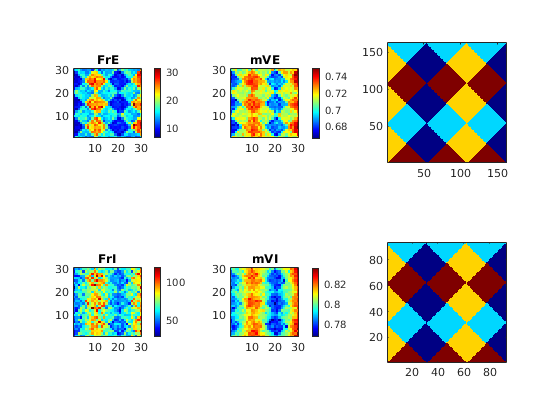

WinSize = 7500;
Window = [T-WinSize T];
EffSize = Window(2)-max(0,Window(1));

h = figure('Name','Field_f&V');

% PixelNum per HC
NPixX = 10; %10
NPixY = 10;

subplot 231
ESPinWin = SpE(:,2)>=Window(1) & SpE(:,2)<=Window(2);
SpEGood = SpE(ESPinWin,1);
[SpCN, SpCI] = groupcounts(SpEGood);
FrE_temp = zeros(N_E,1);
FrE_temp(SpCI) = SpCN*1e3/(EffSize);
FrE_Map = reshape(FrE_temp,N_HC*n_E_HC,N_HC*n_E_HC); % not used here

[FrEPixMat,NnEPixel] = NeuVec2Pixel(FrE_temp,NnE,NPixX*N_HC,NPixY*N_HC);
imagesc(FrEPixMat); title('FrE')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar

subplot 234
ISPinWin = (SpI(:,2)>=Window(1) & SpI(:,2)<=Window(2));
SpIGood = SpI(ISPinWin,1);
[SpCN, SpCI] = groupcounts(SpIGood);
FrI_temp = zeros(N_I,1);
FrI_temp(SpCI) = SpCN*1e3/EffSize;
FrI_Map = reshape(FrI_temp,N_HC*n_I_HC,N_HC*n_I_HC);

[FrIPixMat,NnIPixel] = NeuVec2Pixel(FrI_temp,NnI,NPixX*N_HC,NPixY*N_HC);
imagesc(FrIPixMat); title('FrI')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar

Win2Col = floor((Window)/(T/size(mVE,2)));
SmallWinRange = Win2Col(1):Win2Col(2);
subplot 232
mVE_temp = nanmean(mVE(:,SmallWinRange),2);
mVE_Map = reshape(mVE_temp,N_HC*n_E_HC,N_HC*n_E_HC);

[mVEPixMat,~] = NeuVec2Pixel(mVE_temp,NnE,NPixX*N_HC,NPixY*N_HC);
imagesc(mVEPixMat); title('mVE')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar

subplot 235
mVI_temp = nanmean(mVI(:,SmallWinRange),2);
mVI_Map = reshape(mVI_temp,N_HC*n_I_HC,N_HC*n_I_HC);

[mVIPixMat,~] = NeuVec2Pixel(mVI_temp,NnI,NPixX*N_HC,NPixY*N_HC);
imagesc(mVIPixMat); title('mVI')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar

subplot 233
imagesc(OD_EMap);axis square
set(gca,'YDir','normal')

subplot 236
imagesc(OD_IMap);axis square
set(gca,'YDir','normal')


% end of 500ms plot
OPT = find(OD_E == 1);
WORST = find(OD_E == 3);
MID = find(OD_E == 2 | OD_E == 4);
tt = -T:dt:0;
hSpCount = figure('Name','SpCount')
for subInd = 1:4
    subplot(4,1,subInd)
    NeuInd = MID(subInd);
    hold on
    hist(SpE(ismember(SpE(:,1),NeuInd),2),0:50:T)
    OnOff = double(~logical(floor(mod(PhaseE(NeuInd)+tt,tMod)/MaxOnPhase)));
    plot(tt+T,OnOff,'r')
    xlim([0 5000])
    xlabel('T (ms)')
    ylabel('Sp Count (per 100ms)')
    
end
    


%save('DriveWkSp.mat')

## MF linear equation for pixels: 1 Matrices

FrEPixVec = reshape(FrEPixMat,NPixX*N_HC*NPixY*N_HC,1);
FrIPixVec = reshape(FrIPixMat,NPixX*N_HC*NPixY*N_HC,1);
mVEPixVec = reshape(mVEPixMat,NPixX*N_HC*NPixY*N_HC,1);
mVIPixVec = reshape(mVIPixMat,NPixX*N_HC*NPixY*N_HC,1);
% First, get connectivity matrix between Pixels
C_EE_Pixel = zeros(length(FrEPixVec));
C_EI_Pixel = zeros(length(FrEPixVec));
C_IE_Pixel = zeros(length(FrEPixVec));
C_II_Pixel = zeros(length(FrEPixVec));
% look into std as well
C_EE_Pixelstd = zeros(length(FrEPixVec));
C_EI_Pixelstd = zeros(length(FrEPixVec));
C_IE_Pixelstd = zeros(length(FrEPixVec));
C_II_Pixelstd = zeros(length(FrEPixVec));
tic
AA = length(FrEPixVec);
parfor PixIndPost = 1:AA
    for PixIndPre = 1:AA
        C_EE_Pixel(PixIndPost,PixIndPre) = mean(sum(C_EE_Fix(NnEPixel.Vec == PixIndPost, NnEPixel.Vec == PixIndPre),2));
        C_EI_Pixel(PixIndPost,PixIndPre) = mean(sum(C_EI_Fix(NnEPixel.Vec == PixIndPost, NnIPixel.Vec == PixIndPre),2));
        C_IE_Pixel(PixIndPost,PixIndPre) = mean(sum(C_IE_Fix(NnIPixel.Vec == PixIndPost, NnEPixel.Vec == PixIndPre),2));
        C_II_Pixel(PixIndPost,PixIndPre) = mean(sum(C_II_Fix(NnIPixel.Vec == PixIndPost, NnIPixel.Vec == PixIndPre),2));
        C_EE_Pixelstd(PixIndPost,PixIndPre) = std(sum(C_EE_Fix(NnEPixel.Vec == PixIndPost, NnEPixel.Vec == PixIndPre),2));
        C_EI_Pixelstd(PixIndPost,PixIndPre) = std(sum(C_EI_Fix(NnEPixel.Vec == PixIndPost, NnIPixel.Vec == PixIndPre),2));
        C_IE_Pixelstd(PixIndPost,PixIndPre) = std(sum(C_IE_Fix(NnIPixel.Vec == PixIndPost, NnEPixel.Vec == PixIndPre),2));
        C_II_Pixelstd(PixIndPost,PixIndPre) = std(sum(C_II_Fix(NnIPixel.Vec == PixIndPost, NnIPixel.Vec == PixIndPre),2));
    end    
end
toc
C_EE_Pixel_Us = sparse(C_EE_Pixel);
C_IE_Pixel_Us = sparse(C_IE_Pixel);
C_EI_Pixel_Us = sparse(C_EI_Pixel);
C_II_Pixel_Us = sparse(C_II_Pixel);

% Present connectivity mats
figure
subplot 221
imagesc(C_EE_Pixel)
colormap jet
colorbar
axis square
title('Mean of connectivities')
subplot 222
imagesc(C_EE_Pixelstd)
axis square
colorbar
title('Std of connectivities')
subplot 223
imagesc(C_EE_Pixelstd./C_EE_Pixel)
axis square
colorbar
title('std/mean')

MF linear equation for pixels: 2 MF Eqns

% Mats
MatEE = (S_EE*(1-p_EEFail))*C_EE_Pixel_Us.*(Ve-repmat(mVEPixVec,1,NPixX*N_HC*NPixY*N_HC)); % Need Ref here??
MatEI = S_EI *              C_EI_Pixel_Us.*(Vi-repmat(mVEPixVec,1,NPixX*N_HC*NPixY*N_HC));
MatIE = S_IE *              C_IE_Pixel_Us.*(Ve-repmat(mVIPixVec,1,NPixX*N_HC*NPixY*N_HC));
MatII = S_II *              C_II_Pixel_Us.*(Vi-repmat(mVIPixVec,1,NPixX*N_HC*NPixY*N_HC));
ConnMat = [MatEE,MatEI;
           MatIE,MatII];
% Leak
LeakE = gL_E * (0-mVEPixVec) * 1e3;
LeakI = gL_I * (0-mVIPixVec) * 1e3;
LeakV = [LeakE;LeakI];
% Ext
lambda_E_Pixel = zeros(size(mVEPixVec));
L6E_Pixel = zeros(size(mVEPixVec));
L6I_Pixel = zeros(size(mVEPixVec));
for PixInd = 1:length(FrEPixVec)
    lambda_E_Pixel(PixInd) = mean(lambda_E_drive(NnEPixel.Vec == PixInd));
    L6E_Pixel(PixInd) = mean(rE_L6_Drive(NnEPixel.Vec == PixInd));
    L6I_Pixel(PixInd) = mean(rI_L6_Drive(NnIPixel.Vec == PixInd));
end
lambda_I_Pixel = lambda_I_drive;

ExtE = (lambda_E_Pixel*S_Elgn + rE_amb*S_amb + L6E_Pixel*S_EL6).*(Ve-mVEPixVec) * 1e3;
ExtI = (lambda_I_Pixel*S_Ilgn + rI_amb*S_amb + L6I_Pixel*S_IL6).*(Ve-mVIPixVec) * 1e3;
ExtV = [ExtE;ExtI];
% Ref Vec
RefE = 1-FrEPixVec*tau_ref/1e3;
RefI = 1-FrIPixVec*tau_ref/1e3;
RefM = sparse(diag([RefE;RefI]));
% L4 Frs
Fr_L4 = [FrEPixVec;FrIPixVec];

% MF Equations:
Fr_MF = RefM * (ConnMat*Fr_L4 + ExtV + LeakV);
tic
Fr_MFinv = (sparse(eye(2*NPixX*N_HC*NPixY*N_HC))-RefM*ConnMat) \ (RefM * ( ExtV + LeakV));
toc
% Err
FrErr = Fr_MFinv - Fr_L4;

EPixRange = [0 35];
IPixRange = [10 120]

figure('Name','MF and Real Fr')
a1 = subplot (241);
PS = get(a1,'Position');
imagesc(FrEPixMat); title('FrE')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar; % caxis([20 30])
set(a1,'Position',PS)
caxis(EPixRange);

a5 = subplot (245);
PS = get(a5,'Position');
imagesc(FrIPixMat); title('FrI')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar; % caxis([20 80])
set(a5,'Position',PS)
caxis(IPixRange);

a2 = subplot (242);
PS = get(a2,'Position');
FrEPixMat_MF = reshape(Fr_MFinv(1:length(FrEPixVec)),NPixY*N_HC,NPixX*N_HC)
imagesc(FrEPixMat_MF); title('FrE_{MF}')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar; % caxis([20 30])
set(a2,'Position',PS)
caxis(EPixRange);

a6 = subplot (246);
PS = get(a6,'Position');
FrIPixMat_MF = reshape(Fr_MFinv(length(FrEPixVec)+1:end),NPixY*N_HC,NPixX*N_HC)
imagesc(FrIPixMat_MF); title('FrI_{MF}')
set(gca,'YDir','normal')
axis square
colormap jet
colorbar; % caxis([20 80])
set(a6,'Position',PS)
caxis(IPixRange);

subplot 243
imagesc(OD_EMap);axis square
set(gca,'YDir','normal')

subplot 247
imagesc(OD_IMap);axis square
set(gca,'YDir','normal')

subplot 244
scatter(FrEPixVec,Fr_MFinv(1:NPixX*N_HC*NPixY*N_HC),'ro')
axis([EPixRange EPixRange])
axis square
xlabel('FrE'); ylabel('FrE_MF')

subplot 248
scatter(FrIPixVec,Fr_MFinv(NPixX*N_HC*NPixY*N_HC+1:end),'bo')
 axis([IPixRange IPixRange])
axis square
xlabel('FrI'); ylabel('FrI_MF')

Result not very good. On the other hand, should concern real input since we are only averaging from 25/8 neurons?

Check code: Mistakes in row and column?